%Create datastores
blurDir = fullfile('.','nah','train_blur','train','train_blur');
sharpDir = fullfile('.','nah','train_sharp','train','train_sharp');
n = 24000-1;
order = randperm(n,n);
blurimds = imageDatastore(blurDir,"IncludeSubfolders",1);
trueimds = imageDatastore(sharpDir,"IncludeSubfolders",1);

train_sub = subset(blurimds,order);
label_sub = subset(trueimds,order);
train_subT = transform(train_sub,@findWindow);
label_subT = transform(label_sub,@findWindow);

%combine input and label
dsTrain2 = transform(combine(train_subT,label_subT), @separate);

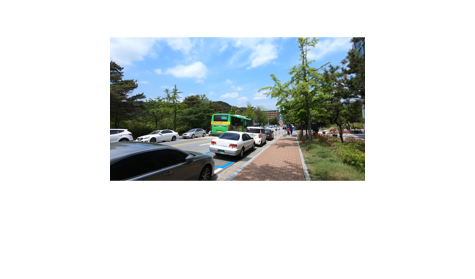

blurImg = train_subT.read();    
imshow(blurImg)

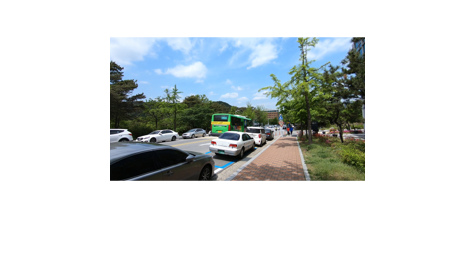

trueImg = label_subT.read();
imshow(trueImg)

ssim(blurImg,trueImg)

ans = 0.9987

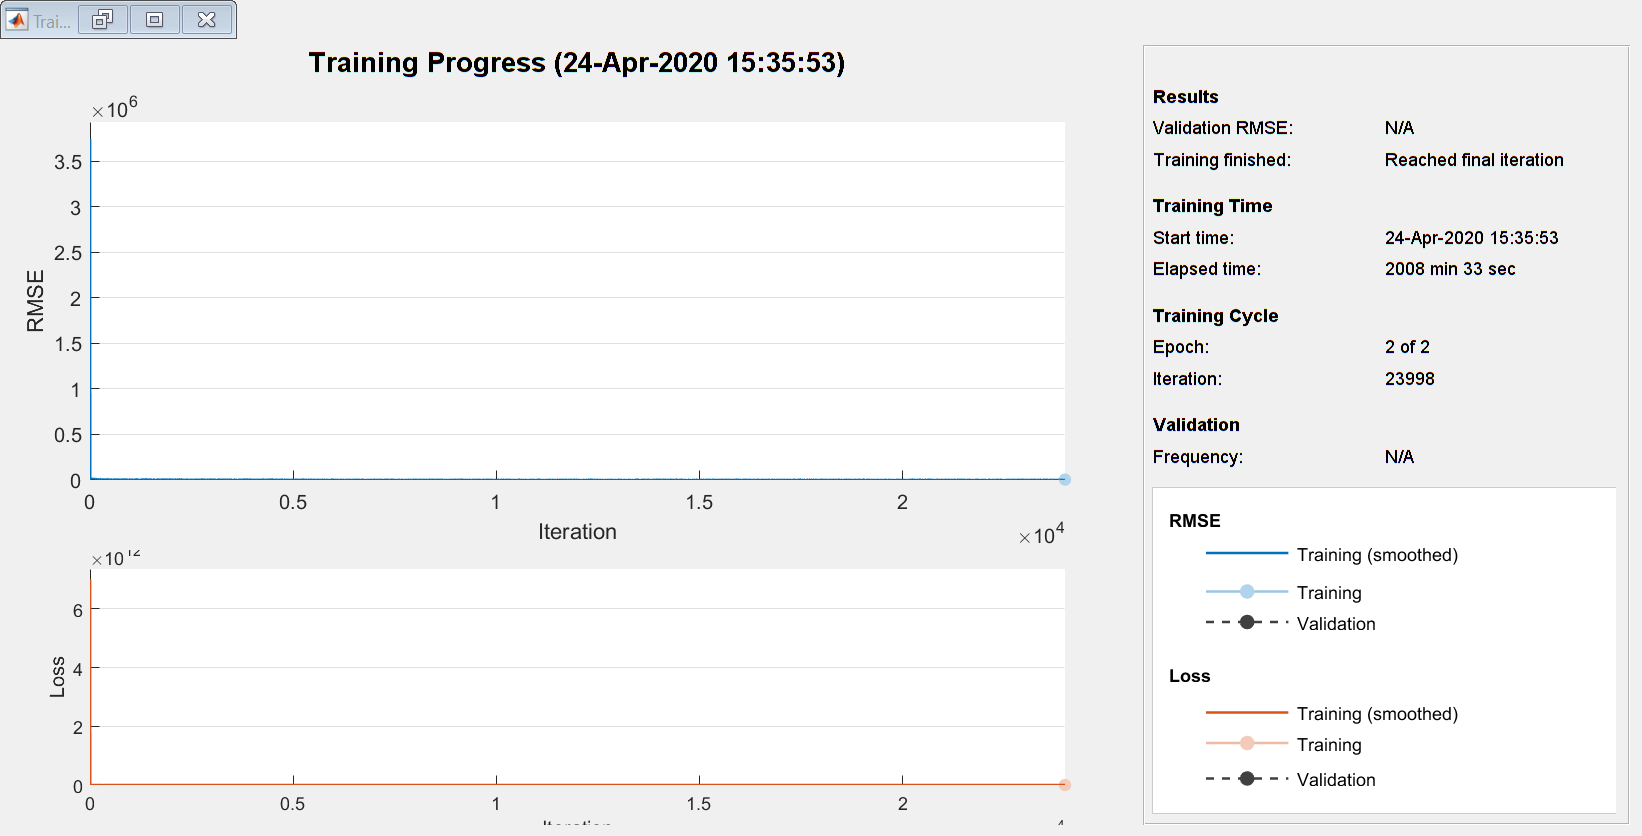

lgraph = unetLayers([144 256 3] , 3,'encoderDepth',3);
lgraph = lgraph.removeLayers('Softmax-Layer');
lgraph = lgraph.removeLayers('Segmentation-Layer');
lgraph = lgraph.addLayers(regressionLayer('name','regressionOutput'));
lgraph = lgraph.connectLayers('Final-ConvolutionLayer','regressionOutput');
maxEpochs = 2;
epochIntervals = 1;
initLearningRate = 0.1;
learningRateFactor = 0.1;
l2reg = 0.0001;
options = trainingOptions('adam', ...
    'MaxEpochs',maxEpochs, ...
    'MiniBatchSize',2, ...
    'Shuffle','never', ...
    'Plots','training-progress', ...
    'Verbose',0);
net = trainNetwork(dsTrain2,lgraph,options);

modelDateTime = datestr(now,'dd-mmm-yyyy-HH-MM-SS');
save(['E2E trainedNet-' modelDateTime '-Epoch-' num2str(maxEpochs*epochIntervals) ...
            'ScaleFactors-' num2str(234) '.mat'],'net','options');

order = randperm(3000,20);
testBlur = transform(subset(imageDatastore(fullfile('.','nah','val_blur','val','val_blur'),"IncludeSubfolders",1),order),@findWindow);
testTrue = transform(subset(imageDatastore(fullfile('.','nah','val_sharp','val','val_sharp'),"IncludeSubfolders",1),order),@findWindow);

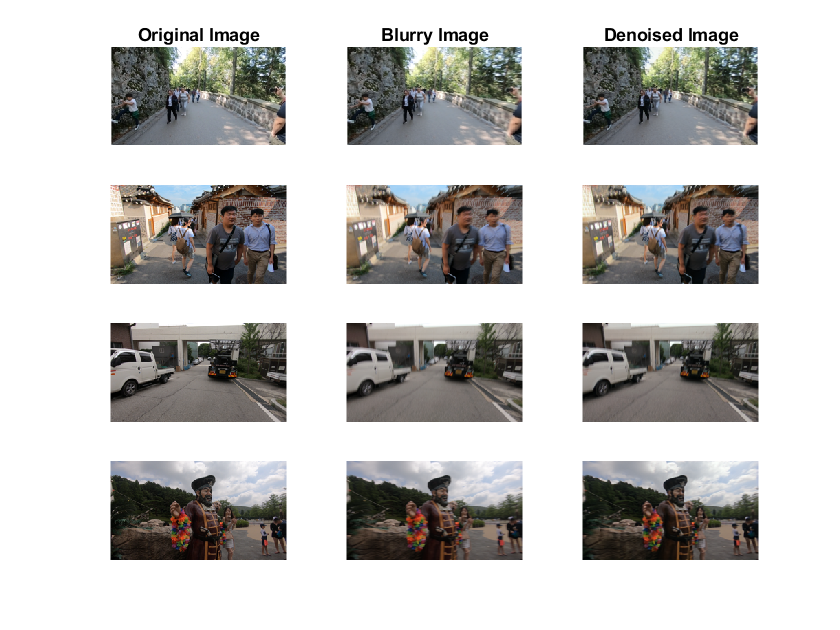

n = 4;
figure; 
subplot(n,3,1);
for k = 1:n
    testImage = testTrue.read();
    blurredImage = testBlur.read();
    subplot(n,3,1 + 3*(k-1));
    imshow(testImage);
    if k == 1
        title('Original Image');  
    end
    
    
    subplot(n,3,2 + 3*(k-1));  
    imshow(blurredImage);
    if k == 1
        title('Blurry Image');
    end
    
    Ideblurred = activations(net,blurredImage,'regressionOutput');
    subplot(n,3,3 + 3*(k-1));
    Iapprox = rescale(Ideblurred);
    Iapprox = im2uint8(Iapprox);
    imshow(Iapprox)
    if k == 1
        title('Denoised Image')
    end
    %imwrite(testImage,['TrueImg' num2str(k) '.png'])
    %imwrite(blurredImage,['BlurImg' num2str(k) '.png'])
    %imwrite(Iapprox,['DeblurImg' num2str(k) '.png'])
end

function dataOut = findWindow(data)
    s = [144 256];%[160 240];
    ratio = s(2)/s(1);
    imSize = size(data);
    scale = min(imSize(1)*ratio,imSize(2));
    windowSize = floor([scale/ratio scale]);
    adjustment = floor(([imSize(1) imSize(2)]- windowSize)/2);
    dataOut = data(1+adjustment(1):windowSize(1)+adjustment(1),1+adjustment(2):windowSize(2)+adjustment(2),:);
    dataOut = imresize(dataOut,s);
end
function dataOut = separate(dataIn)
    p1 = dataIn(:,1:256,:);%dataIn(:,1:240,:);
    p2 = dataIn(:,257:512,:);%dataIn(:,241:480,:);
    dataOut = {p1, p2};
end